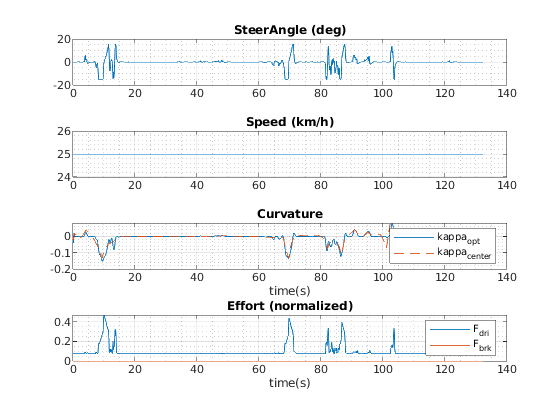

num_start=1;
num_end= 940;
plot_num= num_start:num_end;

close all;

figure;
subplot(4,1,1)
plot(time.x_T_(plot_num),u.x_Delta(plot_num)*(180/pi))
grid on; grid minor;
title('SteerAngle (deg)')

subplot(4,1,2)
plot(time.x_T_(plot_num),x.Var1(plot_num)*(3.6));
grid on; grid minor;
title('Speed (km/h)')

subplot(4,1,3)
plot(time.x_T_(plot_num),kappa_opt.x_Kappa_opt(plot_num))
hold on;
plot(time.x_T_(plot_num),kappa_cen.x_Kappa_center(plot_num),'--')
hold off;
grid on; grid minor;
legend('kappa_{opt}', 'kappa_{center}')
xlabel('time(s)')
title('Curvature')

subplot(4,1,4)
plot(time.x_T_(plot_num),u.F_drive(plot_num)/(1091))
hold on;
plot(time.x_T_(plot_num),u.F_brake(plot_num)/(1800))
hold off;
grid on; grid minor;
legend('F_{dri}', 'F_{brk}')
xlabel('time(s)')
title('Effort (normalized)')

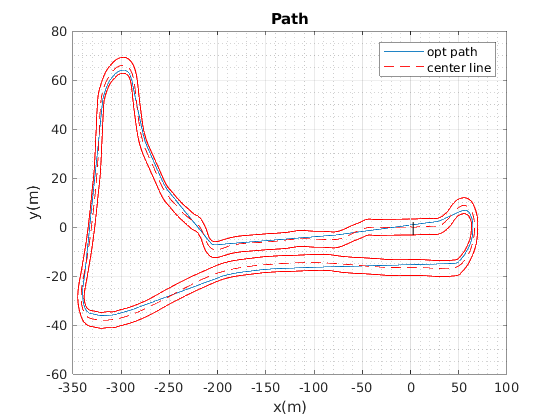


figure()
plot(path_opt.x_Traj_x(plot_num), path_opt.traj_y(plot_num))
hold on
plot(path_og.x_Track_x(plot_num), path_og.track_y(plot_num), 'red', 'LineStyle',"--")
hold on;
plot(london_outer.x_X, london_outer.y, 'red', 'LineWidth', 1.0)
hold on;
plot(london_inner.x_X, london_inner.y, 'red','LineWidth', 1.0)
hold off;
grid on; grid minor;
text(0,0,'|','color', 'black')
legend('opt path', 'center line', "Location", 'Northeast')
xlabel('x(m)');
ylabel('y(m)');
title('Path')

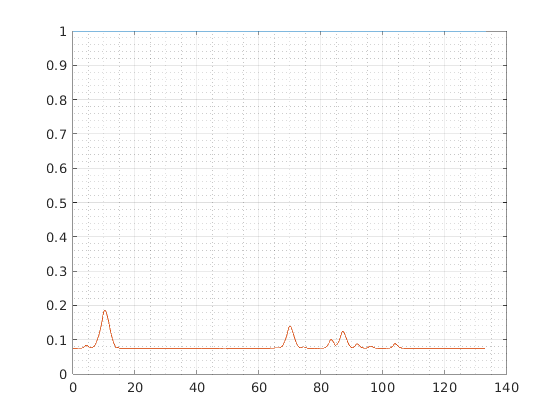

% speed vs drive effort
figure();
plot(time.x_T_(plot_num),x.Var1(plot_num)*(3.6)/25);
hold on;
plot(time.x_T_(plot_num),u.F_drive(plot_num)/(1091));
hold off;
grid on; grid minor;